## Blatt 6

clear;clc;

## Aufgabe 1


$$$\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=t^2 e^{-5 t}-6 \phi(t)$$$
 


$$$\phi(t)=e^{-5 t}\left(t^2-2 t+2\right)-2 e^{-6 t}$$$


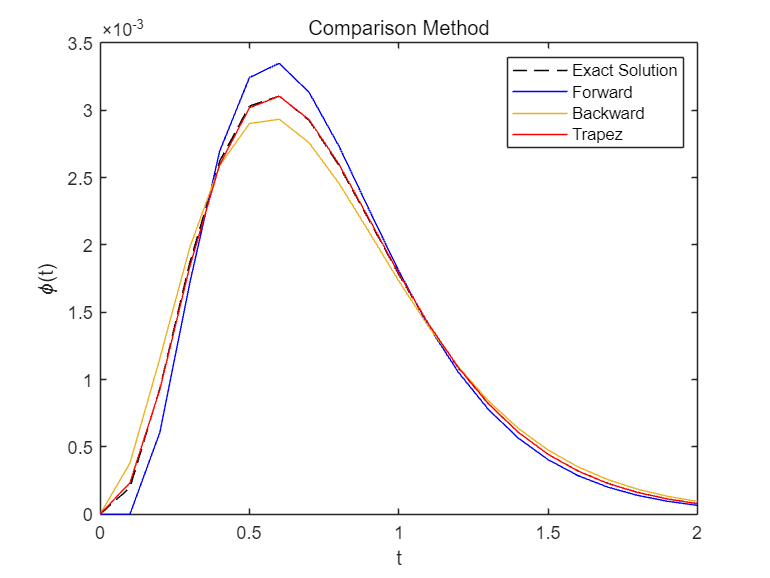

% Parameter setting

theta=[0,1,1/2];
% Vorwärts-Euler Verfahren
t0=0:0.1:2;
phi_exact=exactSolution(t0);
phi_forward=forwardEuler(0,2,0.1);
phi_backward=backwardEuler(0,2,0.1);    
phi_trapez=trapezEuler(0,2,0.1);  
% Exact
plot(t0, phi_exact, '--k','DisplayName','Exact Solution'); 
xlabel('t');
ylabel('\phi(t)');
title('Comparison Method');

hold on
% Foreward
plot(t0, phi_forward, '-blue','DisplayName','Forward'); 

% Backward
plot(t0, phi_backward, 'LineStyle', '-', 'Color', [0.9290 0.6940 0.1250],'DisplayName','Backward');

% Trapez
plot(t0, phi_trapez, '-r','DisplayName','Trapez');
hold off
% 添加图例和坐标轴标签等
legend;

## Aufgabe 2

## 2.1 Test mit Einschritt

% Test Einschritt-θ-Verfahren für θ = 0.0, 0.5 und 1.0. 
[LHS,RHS] = OST(0.5, 0.2, [1.1], [1.4, 1.5], [1.7, 1.8], [2.0])

LHS = 0.9600

RHS = 2.8500

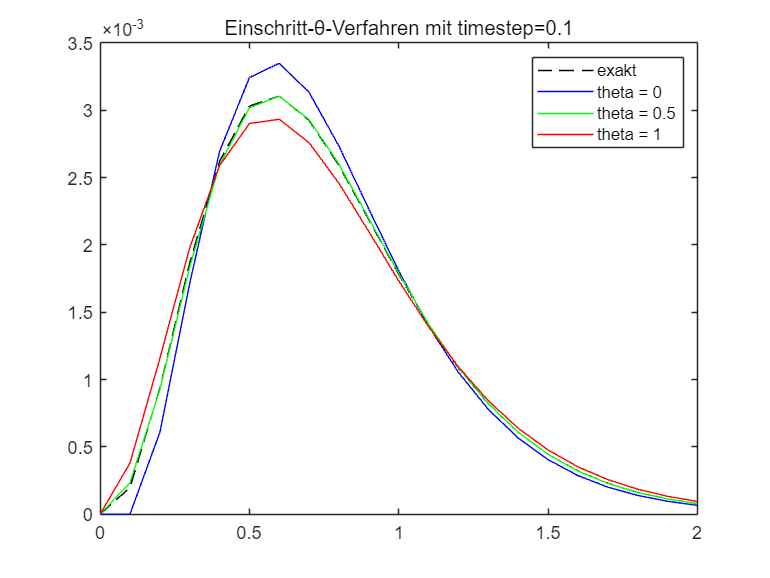

n = size(t0,2);
M = 1; B = [-6,-6];
t0=0:0.1:2;
phi_ost = zeros(n,3);

for i = 1:n-1
    C = [g(t0(i+1)),g(t0(i))];
    [LHS,RHS] = OST(0.0,0.1,M,B,C,phi_ost(i,1));
    phi_ost(i+1,1) = RHS / LHS;
    [LHS,RHS] = OST(0.5,0.1,M,B,C,phi_ost(i,2));
    phi_ost(i+1,2) = RHS / LHS;
    [LHS,RHS] = OST(1.0,0.1,M,B,C,phi_ost(i,3));
    phi_ost(i+1,3) = RHS / LHS;
end
phiost_zero = phi_ost(:,1);% theta = 0
faiost_half = phi_ost(:,2);% theta = 0.5
faiost_one = phi_ost(:,3);% theta = 1
% θ = 0.5
figure;
plot(t0,phi_exact,'k--',t0,phiost_zero,'b',t0,faiost_half,'g',t0,faiost_one,'r');
legend('exakt','theta = 0','theta = 0.5','theta = 1');
title('Einschritt-θ-Verfahren mit timestep=0.1');

## 2.2 Vergleich AB2 AM3 BDF2

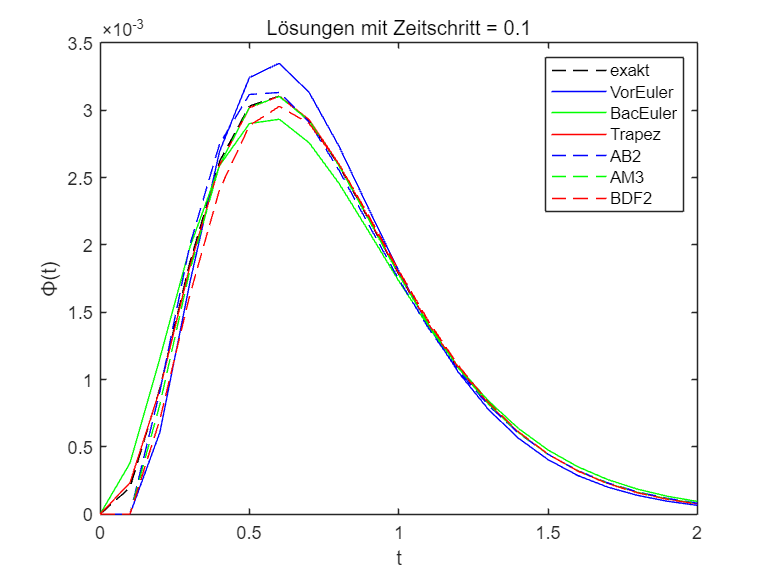

%% Adams-Bashforth-Verfahren
phi_ab2 = zeros(1,n);
M = 1;
for i=2:n-1 % 因为有i-1所以要从2开始
    M = 1;
    B = [-6,-6];
    C = [g(t0(i)),g(t0(i-1))];
    sol = [phi_ab2(i),phi_ab2(i-1)];
    [LHS,RHS] = AB2(0.1,M,B,C,sol);
    phi_ab2(i+1) = RHS / LHS;
end

%% Adams_Moulton-Verfahren
phi_am3 = zeros(1,n);
for i=2:n-1
    B = [-6,-6,-6];
    C = [g(t0(i+1)),g(t0(i)),g(t0(i-1))];
    sol = [phi_am3(i),phi_am3(i-1)];
    [LHS,RHS] = AM3(0.1,M,B,C,sol);
    phi_am3(i+1) = RHS / LHS;
end

%% BDF2-Verfahren
phi_bdf2 = zeros(1,n);
for i=2:n-1
    B = -6;
    C = g(t0(i+1));
    sol = [phi_bdf2(i),phi_bdf2(i-1)];
    [LHS,RHS] = BDF2(0.1,M,B,C,sol);
    phi_bdf2(i+1) = RHS / LHS;
end

figure(2);
plot(t0,phi_exact,'k--',t0,phi_forward,'b',t0,phi_backward,'g',t0,phi_trapez,'r',t0,phi_ab2,'b--',...
    t0,phi_am3,'g--',t0,phi_bdf2,'r--');
legend('exakt','VorEuler','BacEuler','Trapez','AB2','AM3','BDF2');
title('Lösungen mit Zeitschritt = 0.1');
xlabel('t');
ylabel('Φ(t)');

## Funktion

### Funktion


$$\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=f(t, \phi(t))
\\
\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=t^2 e^{-5 t}-6 \phi(t)$$


其中，令$g\left(t\right)=t^2 e^{-5t}$ 方便后续的简化计算

function g=g(t)
g=t^2 * exp(-5*t);
end
function dphi = odeFun(t, phi)
    dphi = g(t) - 6*phi;
end

function phi = exactSolution(t)
    phi = exp(-5*t) .* (t.^2 - 2*t + 2) - 2*exp(-6*t);
end

## Vorward Euler

function phi_forward = forwardEuler(t_start, t_end, delta_t)
    t = t_start:delta_t:t_end;
    len = length(t);
    phi = zeros(1, len);
    for n = 1:len-1
        phi(n+1) = phi(n) + delta_t * (g(t(n)) - 6*phi(n));
    end
    phi_forward = phi;
end

## Backward Euler

function  phi_backward=backwardEuler(t_start, t_end, delta_t)
    t = t_start:delta_t:t_end;
    len = length(t);
    phi = zeros(1, len);
    for n=1:len-1
        % n 是数组循环的index,整数，从1到20，不是时间
        % t(n)是时间范围0到2之间的第n个时间
        % 例如在第二次迭代(n=2)时，t应该等于0+0.1*2=0.2s，对应t(n)
        % 区分到底 g(n+1)还是g(t(n+1))
        phi(n+1) = (phi(n)+delta_t*g(t(n+1)))/(1+delta_t*6);% 1+delta_t*6 是简化公式得来的，
        % 这也是为什么没有用odefunc这个函数，而是使用g(t)*一个东西
    end
    phi_backward=phi;
end

## Trapez Euler

function  phi_backward=trapezEuler(t_start, t_end, delta_t)
    t = t_start:delta_t:t_end;
    len = length(t);
    phi = zeros(1, len);
    for n=1:len-1
        % 公式推导见Notability
        phi(n+1) = ((1-3*delta_t)*phi(n)+0.5*delta_t*(g(t(n))+g(t(n+1))))/(1+3*delta_t);
    end
    phi_backward=phi;
end

### Fkt. 9

function [LHS,RHS] = OST(theta,timestep,M,B,C,sol)
%OST
% M: [M],
% B: [B(tn+1),
% B(tn)],
% C: [C(tn+1),C(tn)], 
% sol: [phi(tn)]
% phi0=7;
LHS=M-theta*timestep*B(1);
RHS=(M + (1-theta)*timestep*B(2))*sol + timestep*(theta*C(1) + (1 - theta)*C(2));

end

### Fkt. 10

function [LHS,RHS] = AB2(timestep,M,B,C,sol)
%AB2 此处显示有关此函数的摘要
% M ... [M ], 
% B ... [B(t n ), B(t n −1 )],
% C ... [C(t n ), C(t n −1 )],
% sol ... [ φ (t n ), φ (t n −1 )]]
LHS = M;
RHS = (M+3/2*timestep*B(1))*sol(1) + (3*timestep/2)*C(1)...
      - timestep/2*B(2)*sol(2)-timestep/2*C(2);

end

### Fkt. 11

function [LHS,RHS] = AM3(timestep,M,B,C,sol)
% M ... [M],
% B ... [B(t n+1 ), B(t n ), B(t n −1 )],
% C ... [C(t n+1 ), C(t n ), C(t n −1 )],
% sol ... [ φ (t n ), φ (t n −1 )]]
LHS = M - 5/12*timestep*B(1);
RHS =(M + 2/3*timestep*B(2))*sol(1) + 5/12*timestep*C(1) + 2/3*timestep*C(2)...
     - timestep/12*(B(3)*sol(2) + C(3));
end

### Fkt. 12

function [LHS,RHS] = BDF2(timestep,M,B,C,sol)
% M ... [M ],
% B ... [B(t n+1 )],
% C ... [C(t n+1 )],
% sol ... [ φ (t n ), φ (t n −1 )]]
LHS = 3/2*M - timestep*B;
RHS = 2*M*sol(1) - 0.5*M*sol(2) + timestep*C;
end